kappa_ext = 1.2323e6;
kappa_int = .22653e6;
% kappa_int = 0; % Wustmann fig 5 param
kappa_tot = kappa_ext + kappa_int; %kappa_int = 0.2265MHz. These values correspond to ng = 0 and phi = 0 for Jules' sample in March 2021 small fridge
% kerr = 0;
kerr = .5e6;
% kerr = kappa_tot/ 2 / 100; % Wustmann fig 5 param
detunings = linspace(-4*kappa_tot, 2*kappa_tot, 1000);
detunings_spacing_1 = mean(abs(diff(detunings)));
omega_0 = 5.7851e9; % in Hz. 
h = 6.626e-34; % just h, not hbar since omega_0 is in Hz
plot_figures = 1;
% flux_pump = 0;
flux_pump = 1.5*kappa_tot/2; % epsilon in Wustmann PRB 2013 (our kappa_tot/2 = \Gamma in PRB)
power_specific_in_dBm = - 130; % in dBm at sample capacitor
power_input_watts = 1e-3*10^(power_specific_in_dBm/10);
power_input_number = power_input_watts/h/omega_0;  % remember this is photon flux - per second
% power_input_number = 2 * kappa_tot/2; % Wustmann fig 5 param
kerr = kerr/1e6;
kappa_ext = kappa_ext /1e6;
kappa_tot = kappa_tot/ 1e6;
detunings = detunings/ 1e6;
power_input_number = power_input_number /1e6;
flux_pump = flux_pump / 1e6;
input_phase = pi/2;
pump_phase = 0;

amp_roots = zeros(length(detunings), 5);

for i = 1 : length(detunings)
    amp_roots(i,:) = roots([kerr^4, 4*kerr^3*detunings(i), 6*detunings(i)^2*kerr^2 + kappa_tot^2*kerr^2/2 - ...
        2*kerr^2*flux_pump^2 , 4*detunings(i)^3*kerr + detunings(i) * kerr*kappa_tot^2 - 4*detunings(i)*kerr*flux_pump^2 - ...
        power_input_number*kappa_ext*kerr^2, detunings(i)^4 + kappa_tot^4/16 + flux_pump^4 + ...
        detunings(i)^2 * kappa_tot^2/2 - 2*detunings(i)^2*flux_pump^2 - kappa_tot^2*flux_pump^2/2 - ...
        2*power_input_number*kappa_ext*detunings(i)*kerr - 2*flux_pump*kerr*power_input_number*kappa_ext*cos(2*input_phase ...
        + pump_phase), -power_input_number*kappa_ext*(flux_pump^2 + kappa_tot^2/4 + detunings(i)^2 + ...
        2*flux_pump*detunings(i)*cos(2*input_phase + pump_phase) - ...
        2*flux_pump*kappa_tot/2*sin(2*input_phase + pump_phase))]);
    test(i) = (kappa_tot^2/4 + detunings(i)^2)/(kappa_tot^4/16 + kappa_tot^2*detunings(i)^2/2);
end

amp_roots(imag(amp_roots) ~=0) = NaN;

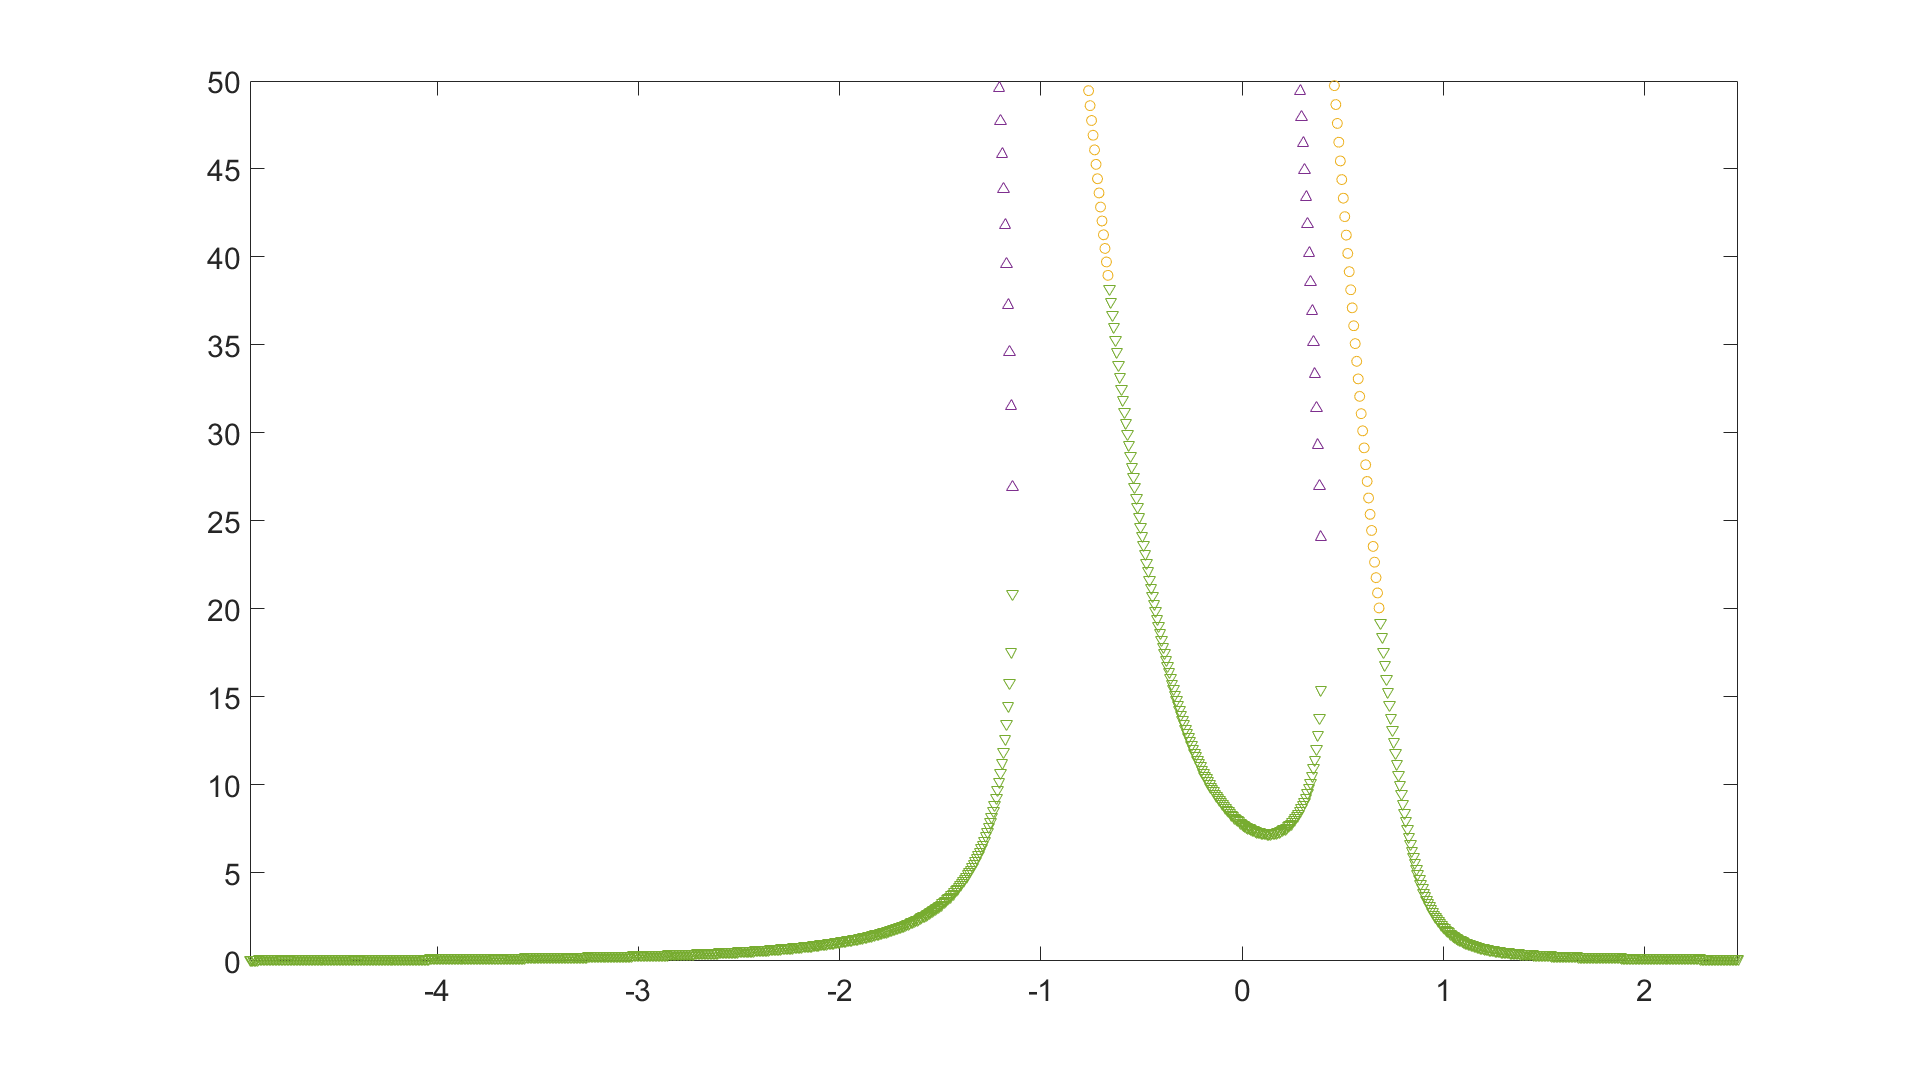

figure
plot(detunings, amp_roots(:,1),'.')
hold on
plot(detunings, amp_roots(:,2),'x')
plot(detunings, amp_roots(:,3),'o')
plot(detunings, amp_roots(:,4),'^')
plot(detunings, amp_roots(:,5),'v')
axis([min(detunings) max(detunings) 0 50])

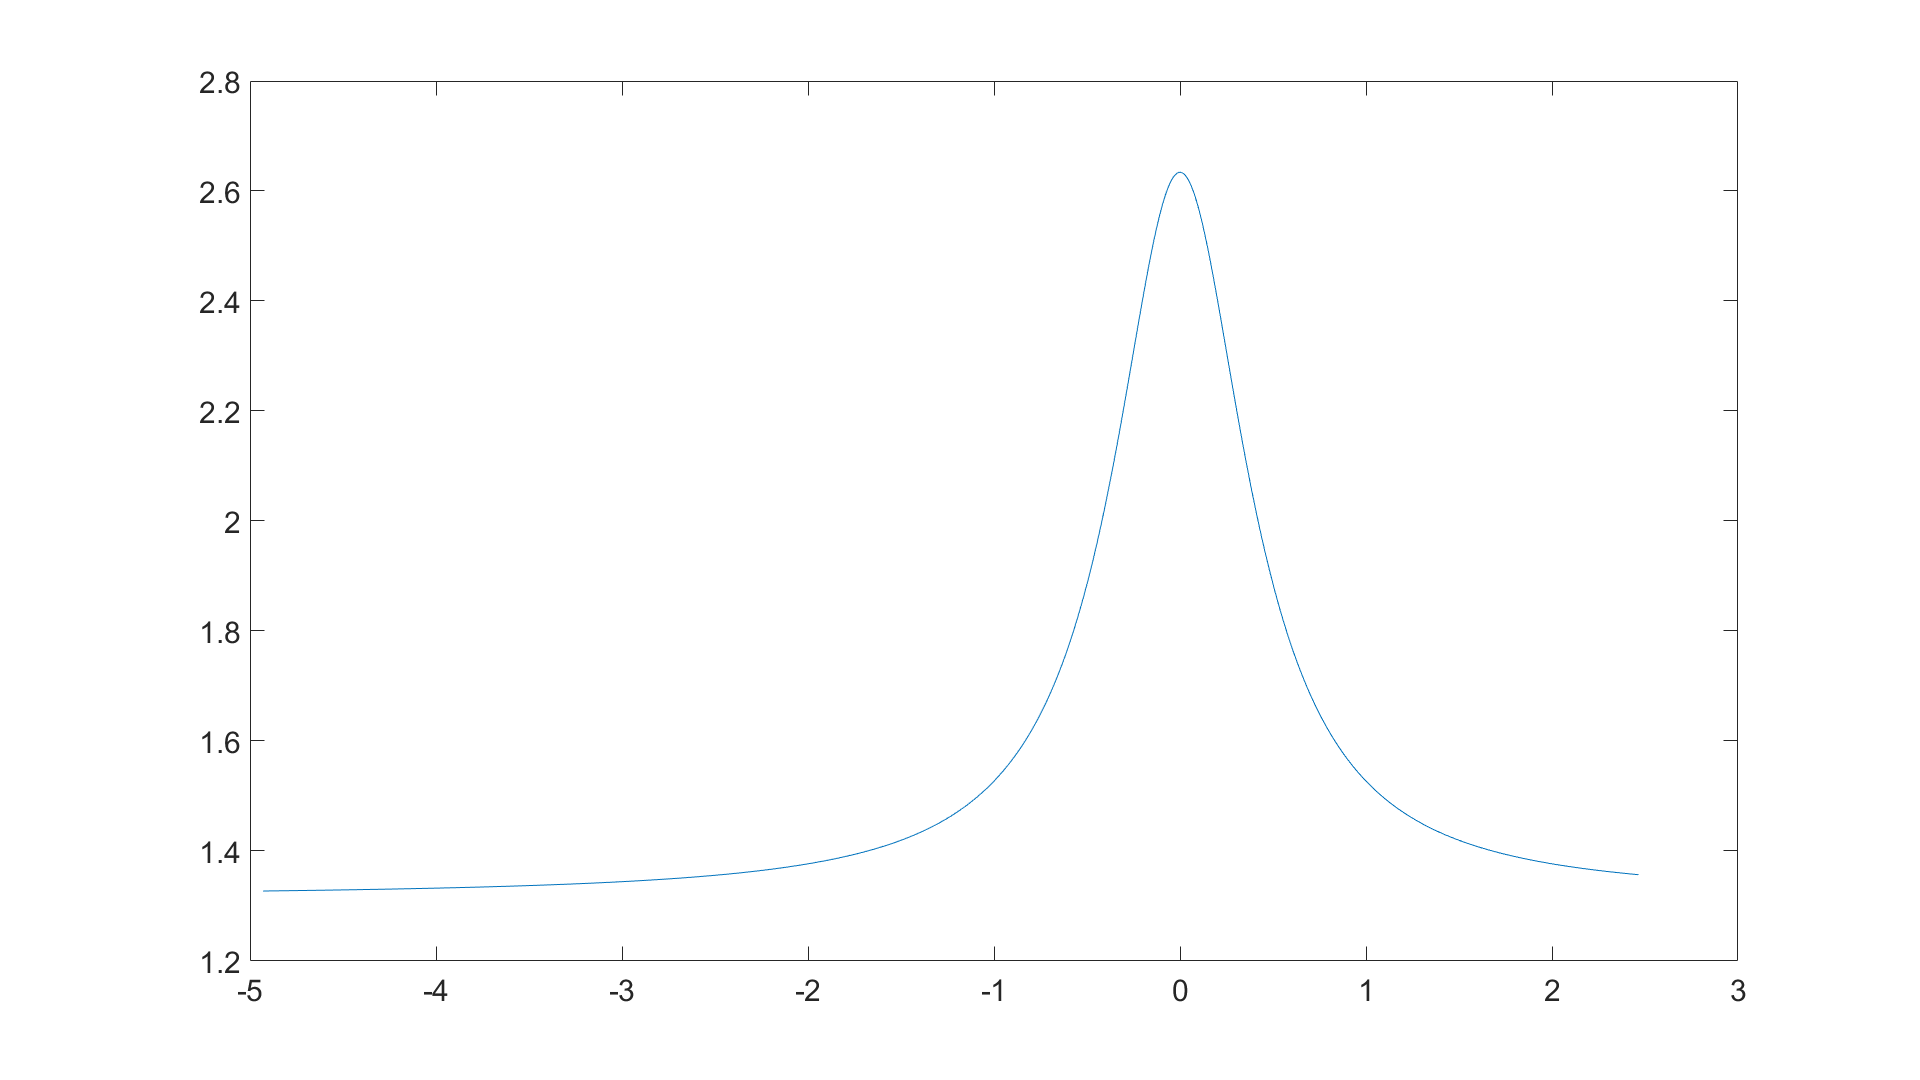

figure
plot(detunings, test)